clear; clc; close all;

%% Load Parameters
quanser_aero_parameters;
quanser_aero_state_space;

% Convert to SS model
G_unc = ss(A, B, C, D);        % uncertain plant
G_nom = G_unc.NominalValue; 

%% Define weights
s = tf('s');
wc = 5;  % crossover frequency in rad/s

% Performance weight: reject DC by 1000x, peak ≤ 3
% Wp = (s/M + wc) / (s + wc*A), A = low freq gain
M = 3;  % sensitivity peak
A = 1/1000;  % low-frequency gain (1/1000 = disturbance rejection of 1000x)

Wp_single = (s/M + wc) / (s + wc*A);
Wp = blkdiag(Wp_single, Wp_single);  % Diagonal

% Control weight: to reduce control effort (tune as needed)
Wu = 0.01 * eye(2);


P_aug = augw(G_nom, Wp, Wu); 


[K_h2, CL_h2, gam_h2] = h2syn(P_aug, 2, 2);

disp("H2 optimal gamma: " + gam_h2);

H2 optimal gamma: Inf


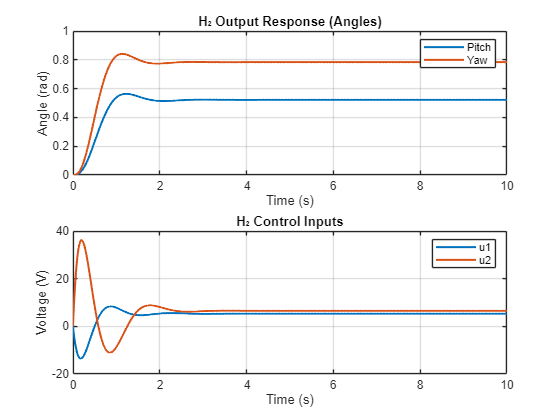



%% Closed-loop system from r to y
T = feedback(G_nom * K_h2, eye(2));  % y = T * r

%% Simulate step tracking
t = 0:0.01:10;
r = [pi/6 * ones(length(t),1), pi/4 * ones(length(t),1)];  % reference: [pitch, yaw]

% Simulate output
[y, ~] = lsim(T, r, t);

% Simulate control input: u = K * (r - y)
e = r - y;
u = lsim(K_h2, e, t);

%% Plot output angles
figure;
subplot(2,1,1);
plot(t, y(:,1), 'LineWidth', 1.5); hold on;
plot(t, y(:,2), 'LineWidth', 1.5);
title('H₂ Output Response (Angles)');
xlabel('Time (s)'); ylabel('Angle (rad)');
legend('Pitch','Yaw'); grid on;

%% Plot control inputs
subplot(2,1,2);
plot(t, u(:,1), 'LineWidth', 1.5); hold on;
plot(t, u(:,2), 'LineWidth', 1.5);
title('H₂ Control Inputs');
xlabel('Time (s)'); ylabel('Voltage (V)');
legend('u1','u2'); grid on;


%% === Robust Stability Check ===
CL_unc = feedback(G_unc * K_h2, eye(2));  % uncertain closed-loop system
[stab_margin, stab_report] = robstab(CL_unc);
disp('--- Robust Stability ---');

--- Robust Stability ---


disp(stab_report);

    Jp: 0.0311
    Jy: 0.0129



RS = 1 / stab_margin.LowerBound;
fprintf('Robust Stability Margin (RS) = %.4f\n', RS);

Robust Stability Margin (RS) = 0.3572


%% === Robust Performance Check ===
P_unc = augw(G_unc, Wp, Wu);        % uncertain generalized plant
CL_perf = lft(P_unc, K_h2);         % closed-loop from w to z
[perf_margin, perf_report] = robustperf(CL_perf);
disp('--- Robust Performance ---');

--- Robust Performance ---


disp(perf_report);

    Jp: 0.0229
    Jy: 0.0230



RP = 1 / perf_margin.LowerBound;
fprintf('Robust Performance Margin (RP) = %.4f\n', RP);

Robust Performance Margin (RP) = 3.1452
